# Time course for the story

## Unstable oscillation

Delta_E = 0.17;
Delta_I = 0.03;
Iattn = 0.02;
time = 4000;

[r,~,~] = once(Delta_E, Delta_I, Iattn, time);
r = r*1000;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;

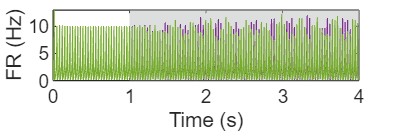

r_cond4 = squeeze(r(1,:,4));
r_cond5 = squeeze(r(1,:,5));
figure();

hold on;

recX = [1 time/1000 time/1000 1];
recY = [0 0 100 100];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.5);
plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.5);

axis([0 time/1000 0 13]);
xlabel("Time (s)");
ylabel("FR (Hz)");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% print('rawC', '-dpng', '-r600');
% print('rawC', '-depsc', '-r600');

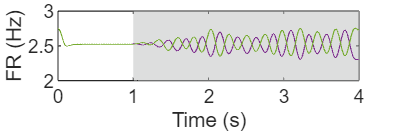

va = 10*100;
r_cond4 = movmean(squeeze(r(1,:,4)),va);
r_cond5 = movmean(squeeze(r(1,:,5)),va);
figure();

hold on;

recX = [1 time/1000 time/1000 1];
recY = [0 0 100 100];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.5);
plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.5);

axis([0 time/1000 2 3]);
xlabel("Time (s)");
ylabel("FR (Hz)");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% print('rawC', '-dpng', '-r600');
% print('rawC', '-depsc', '-r600');

## Sensory only WTA of L2/3E

Delta_E = 0.12;
Delta_I = 0.04;
Iattn = 0.02;
time = 4000;

[r,~,~] = once(Delta_E, Delta_I, Iattn, time);
r = r*1000;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;

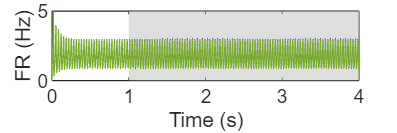

r_cond4 = squeeze(r(1,:,4));
r_cond5 = squeeze(r(1,:,5));
figure();

hold on;

recX = [1 time/1000 time/1000 1];
recY = [0 0 100 100];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.5);
plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.5);

axis([0 time/1000 0 5]);
xlabel("Time (s)");
ylabel("FR (Hz)");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% print('rawC', '-dpng', '-r600');
% print('rawC', '-depsc', '-r600');

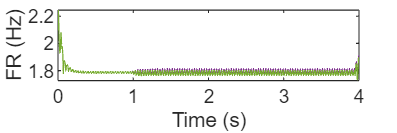

va = 100*100;
r_cond4 = movmean(squeeze(r(1,:,4)),va);
r_cond5 = movmean(squeeze(r(1,:,5)),va);
figure();

hold on;

% recX = [1 time/1000 time/1000 1];
% recY = [0 0 100 100];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.5);
plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.5);

% axis([0 time/1000 2.6 2.8]);
xlabel("Time (s)");
ylabel("FR (Hz)");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% print('rawC', '-dpng', '-r600');
% print('rawC', '-depsc', '-r600');